disp("Linear system, one root")

Linear system, one root


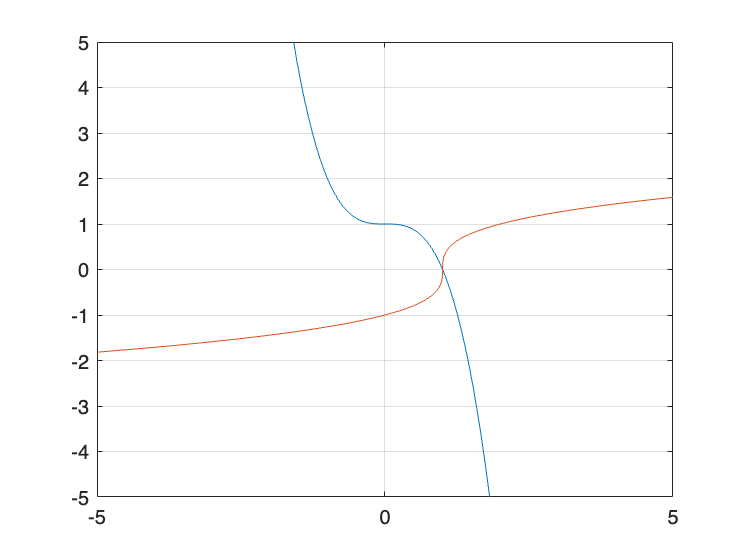


fimplicit(@(x,y) x.^3+y-1,[-5 5 -5 5])
hold on
fimplicit(@(x,y) y.^3-x+1,[-5 5 -5 5])
grid
hold off


function F = F1(X)
F = [X(1)^3+X(2)-1;
    X(2)^3-X(1)+1];
end

function dF = dF1(X)
dF = [3*X(1)^2, 1;
    -1, 3*X(2)^2];
end

sol = NewtonSYS(@F1,@dF1,zeros(2,1))

sol =     1.0000
   -0.0000


sol = TraubSYS(@F1,@dF1,zeros(2,1))

sol =     1.0000
    0.0000


sol = TrapezoidalSYS(@F1,@dF1,zeros(2,1),"maxiter",200)

sol =     1.0000
   -0.0000


sol = Jarrat(@F1,@dF1,zeros(2,1))

sol =     1.0000
    0.0000


sol = HMT(@F1,@dF1,zeros(2,1))

sol =     1.0000
   -0.0000


sol = M5(@F1,@dF1,zeros(2,1),"maxiter",200)

sol =     1.0000
    0.0000


disp("3x3 system, full outputs")

3x3 system, full outputs



function F = F4(X)
F = [3*X(1)-cos(X(2)*X(3))-1/2;
    X(1)^2-625*X(2)^2;
    exp(-X(1)*X(2))+20*X(3)+(10*pi-3)/3];
end

function dF = dF4(X)
dF = [3, X(3)*sin(X(2)*X(3)), X(3)*sin(X(2)*X(3));
    2*X(1), -625*2*X(2),0;
    -X(2)*exp(-X(1)*X(2)),-X(1)*exp(-X(1)*X(2)), 20];
end

disp("Newton")

Newton


[sol, dif, res, ~, iter, ACOC] = NewtonSYS(@F4, @dF4, ones([3,1]));
sol, dif = dif(end), err = res(end), iter, ACOC(end-3:end)

sol =     0.5000
    0.0200
   -0.5231


dif = 8.6139e-11

err = 7.9937e-15

iter = 10

ans =     1.5301    1.8945    1.9928    1.1720



disp("Traub")

Traub


[sol, dif, res, ~, iter, ACOC] = TraubSYS(@F4, @dF4, ones([3,1]));
sol, dif = dif(end), err = res(end), iter, ACOC(end-3:end)

sol =     0.5000
    0.0200
   -0.5231


dif = 5.5511e-17

err = 1.7764e-15

iter = 8

ans =     1.6908    2.7448    1.7088    0.0005




disp("Trapezoidal")

Trapezoidal


[sol, dif, res, ~, iter, ACOC] = TrapezoidalSYS(@F4, @dF4, ones([3,1]),"maxiter",100);
sol, dif = dif(end), err = res(end), iter, ACOC(end-3:end)

sol =     0.5000
    0.0200
   -0.5231


dif = 1.2517e-12

err = 8.9840e-11

iter = 97

ans =     1.0000    1.0000    1.0000    1.0000




disp("Jarrat")

Jarrat


[sol, dif, res, ~, iter, ACOC] = Jarrat(@F4, @dF4, ones([3,1]));
sol, dif = dif(end), err = res(end), iter, ACOC(end-3:end)

sol =     0.5000
    0.0200
   -0.5231


dif = 6.7712e-11

err = 1.8980e-15

iter = 6

ans =     1.1613    2.4082    1.5380    0.9595




disp("HMT")

HMT


[sol, dif, res, ~, iter, ACOC] = HMT(@F4, @dF4, ones([3,1]));
sol, dif = dif(end), err = res(end), iter, ACOC(end-3:end)

sol =     0.5000
    0.0200
   -0.5231


dif = 1.2418e-16

err = 1.7764e-15

iter = 7

ans =     1.5503    3.3302    1.2293    0.0005




disp("M5")

M5


[sol, dif, res, ~, iter, ACOC] = M5(@F4, @dF4, ones([3,1]));
sol, dif = dif(end), err = res(end), iter, ACOC(end-3:end)

sol =     0.5000
    0.0200
   -0.5231


dif = 2.2207e-16

err = 1.7764e-15

iter = 6

ans =     1.1089    2.1284    4.2181    0.0026
